close all
clear all
clc
plot_counter=1;
Question_mark='Q21_disturbance ';

run('BASIC.m')
d=4

d = 4

n=length(A)-1;

[alpha,beta]=d_step_maker(A,B,d);

T_s=0.1;
tfinal=100;
freq=15;
variance=0.01;
C=0;
[uc,t,Status,tfinal,Noix]=Datagen(0,T_s,tfinal,freq,variance,C);
Titlework=[Question_mark,Status];
uc(1:40,1)=ones(40,1);

N=numel(t);
var_y=zeros(1,N);  mean_y=zeros(1,N); ACLS_y=zeros(1,N);
var_u=zeros(1,N);  mean_u=zeros(1,N); ACLS_u=zeros(1,N);
u=zeros(1,N);
y=zeros(1,N);
Normerror=0;
Error=0;
for i=d+n:N-d
    if i>floor(N/3)
        y(i)=-A(2:end)*y(i-1:-1:i-n)'+B*u(i-d:-1:i-length(B)+1-d)'+.1;
    else
        y(i)=-A(2:end)*y(i-1:-1:i-n)'+B*u(i-d:-1:i-length(B)+1-d)';
    end

    u(i)=uc(i+d)-alpha*y(i:-1:i-n+1)'-beta(2:end)*u(i-1:-1:i-n-d+2)';
    if abs(u(i))>3.5
        u(i)=sign(u(i))*3.5;
    end
    var_u (i)=var(u)    ;mean_u(i)=mean(u)  ;ACLS_u(i)=u(i)^2+ACLS_u(i-1)   ;
    var_y(i)=var(y)     ;mean_y(i)=mean(y)  ;ACLS_y(i)=y(i)^2+ACLS_y(i-1)   ;
    Error=(y(i)-uc(i))^2+Error;
    Normerror=norm(Error,2)+Normerror;
end

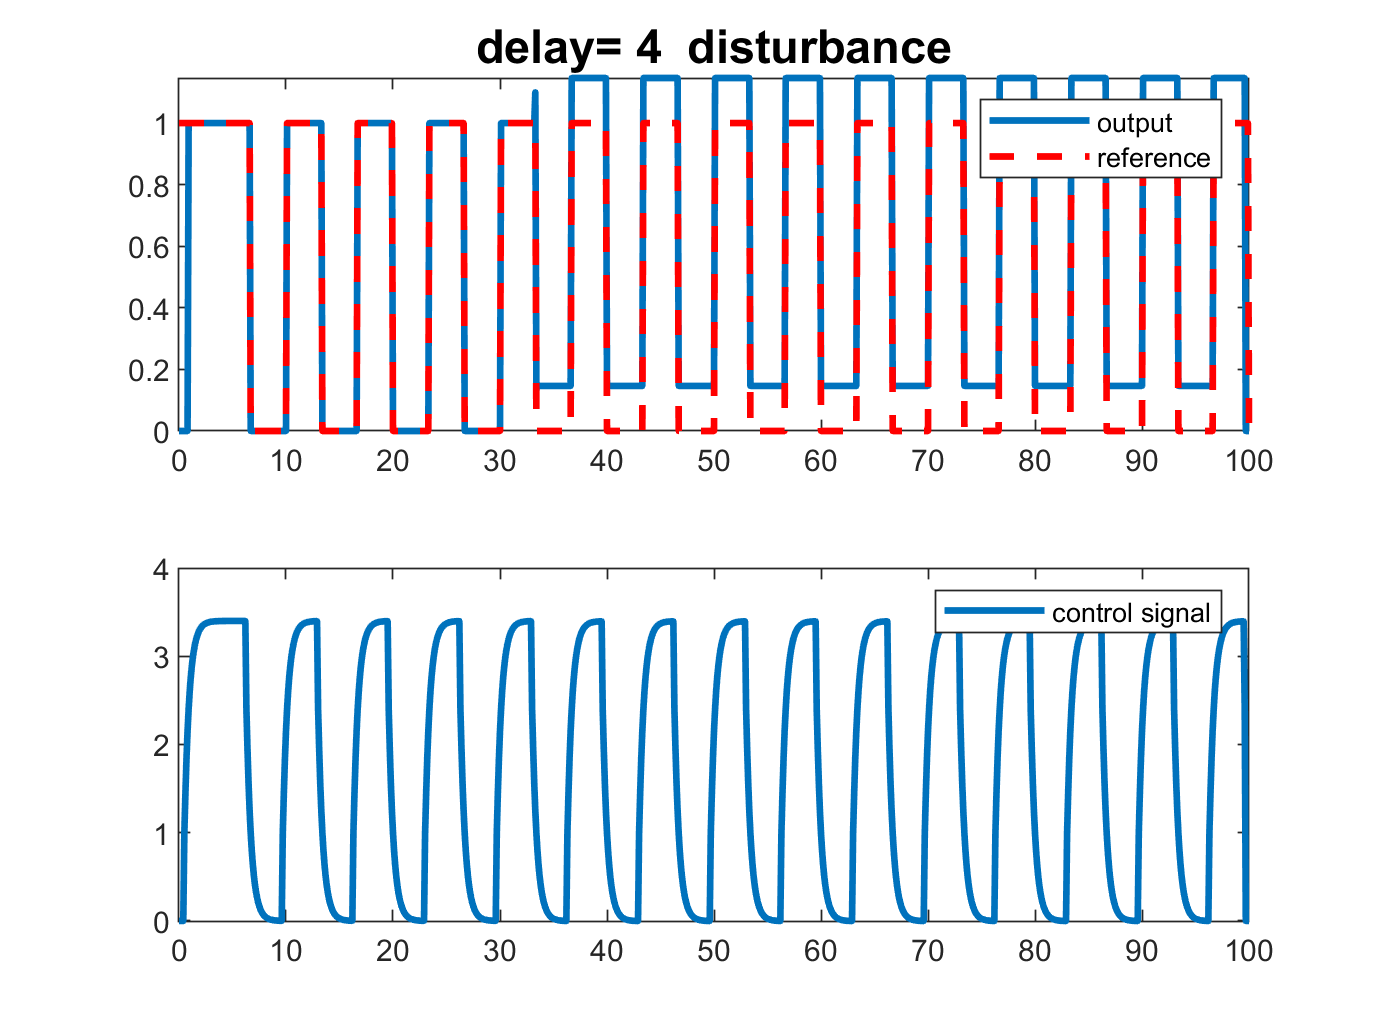

figure(1);
subplot(2,1,1);
    plot(t,y,t,uc','--r','linewidth',2);
    title(['delay= ',num2str(d) '  ', 'disturbance'],'fontsize',14)
    legend('output','reference');

subplot(212);
    plot(t,u,'linewidth',2);
    legend('control signal');

print(gcf,['Q2_disturbance' , ' d=' num2str(d) ' Result.png'],'-dpng','-r400');

plot_counter=plot_counter+1;
disp(['mean of u=',num2str(mean_u(end-d)),'   mean of y=',num2str(mean_y(end-d))])

mean of u=1.7551   mean of y=0.61356


disp(['accumulated loss of u=',num2str(ACLS_u(end-d)),'   accumulated loss of y=',num2str(ACLS_y(end-d))])

accumulated loss of u=5247.1453   accumulated loss of y=627.1936


disp(['Error of u=',num2str(Error),'   NormError of y=',num2str(Normerror)])

Error of u=18.2235   NormError of y=8686.2395
